% setting up inputs (functions are separate m files)
xi = linspace(-4,4,300);
yi = linspace(-4,4,300);
[X,Y] = meshgrid(xi,yi);

Testing 

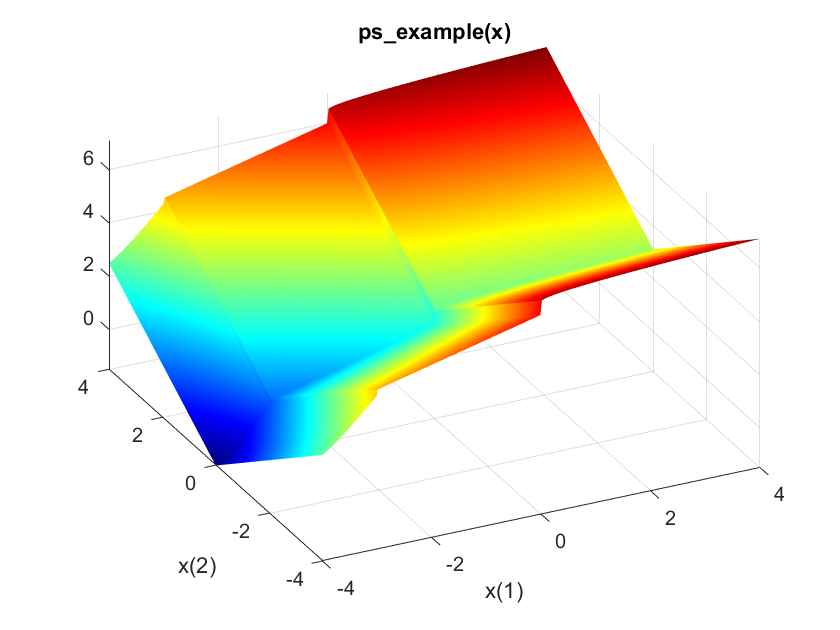

Z = ps_example([X(:),Y(:)]);
Z = reshape(Z,size(X));
surf(X,Y,Z,'MeshStyle','none')
colormap 'jet'
view(-26,43)
xlabel('x(1)')
ylabel('x(2)')
title('ps\_example(x)')


rng default % For reproducibility
x = ga(@ps_example,2)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =    -4.6793   -0.0860


Solving the problem

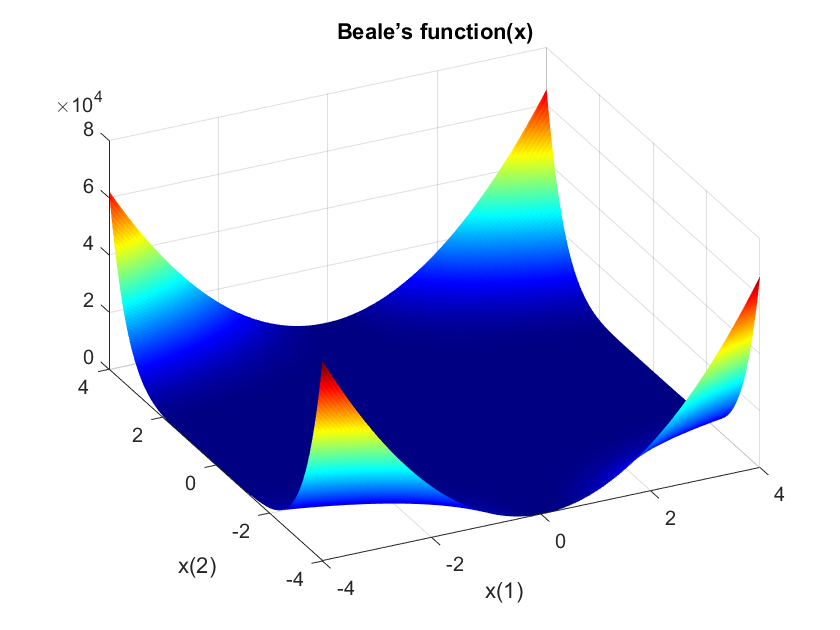

Z2 = ps_example2([X(:),Y(:)]);
Z2 = reshape(Z2,size(X));
surf(X,Y,Z2,'MeshStyle','none')
colormap 'jet'
view(-26,43)
xlabel('x(1)')
ylabel('x(2)')
title('Beale’s function(x)')


options = optimoptions('ga');

rng default % For reproducibility
x2 = ga(@ps_example2,2,options)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x2 =     3.2873    0.4697
